R_0 = [0; 0; 0];  % Anfangsposition (Nullvektor)
V_0 = [0; 0; 0];  % Anfangsgeschwindigkeit (Nullvektor)
t = linspace(0, 120, 240); % Zeitbereich auf eine Minute erweitert

% A ist eine Matrix, die die Beschleunigung in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
% Die Beschleunigung wird durch trigonometrische Funktionen erzeugt.
A = [1 * cos(t/12); 0.5 * sin(t/12); 0.05 * ones(size(t/12))]; 

% V ist eine Matrix, die die Geschwindigkeit in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
% Die Geschwindigkeit wird durch numerische Integration der Beschleunigung berechnet.
% Die Anfangsgeschwindigkeit V_0 wird hinzugefügt.
V = cumtrapz(t/12, A, 2) + V_0;


% R ist eine Matrix, die die Position in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
% Die Position wird durch numerische Integration der Geschwindigkeit und Beschleunigung berechnet.
% Der Anfangsposition R_0 und zusätzlichen Ausdrücken für die Berücksichtigung der Beschleunigung während der Bewegung wird hinzugefügt.
R = R_0 + cumtrapz(t/12, V, 2) + 0.5 * cumtrapz(t/12, A, 2) .* t;

figure(1);
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);  % 'LineWidth', 2 legt die Linienbreite des Plots fest.
xlabel('x');
ylabel('y');
zlabel('z');
grid on;


pos_radar1 = [0, -10, 0];  % Position des Radar 1: x=0, y=-10, z=0
pos_radar2 = [-50, 30, 0];  % Position des Radar 2: x=-50, y=30, z=0

figure;
hold on;  % Aktiviert den "hold on"-Modus, um mehrere Plots in derselben Figur zu zeichnen
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);  % Zeichnet den 3D-Plot der Daten R mit Linienbreite 2

% Zeichnet den Punkt für Radar 1 in Rot mit einem Marker der Größe 20
plot3(pos_radar1(1), pos_radar1(2), pos_radar1(3), 'r.', 'MarkerSize', 20);

% Zeichnet den Punkt für Radar 2 in Rot mit einem Marker der Größe 20
plot3(pos_radar2(1), pos_radar2(2), pos_radar2(3), 'r.', 'MarkerSize', 20);


R_transposed = transpose(R);  % Transponiert die Matrix R

dist_matrix_radar1 = [];
dist_matrix_radar2 = [];

dist_3dmatrix_radar1 = [];
dist_3dmatrix_radar2 = [];

for i = 1:length(R_transposed)
    
    %Berechnung des Absoluten Abstand im 3D-Raum
    dist_radar1 = norm(R_transposed(i, :) - pos_radar1);  % Berechnet den Abstand zwischen der i-ten Zeile von R_transposed und pos_radar1
    dist_radar2 = norm(R_transposed(i, :) - pos_radar2);  % Berechnet den Abstand zwischen der i-ten Zeile von R_transposed und pos_radar2
    
    dist_matrix_radar1 = [dist_matrix_radar1; dist_radar1];  % Fügt den Abstand dist_radar1 der dist_matrix_radar1 hinzu
    dist_matrix_radar2 = [dist_matrix_radar2; dist_radar2];  % Fügt den Abstand dist_radar2 der dist_matrix_radar2 hinzu
    
    %Berechnung des Abstands seperat in x,y,z Richtung
    dist3d_radar1 = [R(1,i)-pos_radar1(1), R(2,i)-pos_radar1(2), R(3,i)-pos_radar1(3)];  % Berechnet den 3D-Abstand zwischen R(:,i) und pos_radar1
    dist3d_radar2 = [R(1,i)-pos_radar2(1), R(2,i)-pos_radar2(2), R(3,i)-pos_radar2(3)];  % Berechnet den 3D-Abstand zwischen R(:,i) und pos_radar2
    
    dist_3dmatrix_radar1 = [dist_3dmatrix_radar1; dist3d_radar1];  % Fügt den 3D-Abstand dist3d_radar1 der dist_3dmatrix_radar1 hinzu
    dist_3dmatrix_radar2 = [dist_3dmatrix_radar2; dist3d_radar2];  % Fügt den 3D-Abstand dist3d_radar2 der dist_3dmatrix_radar2 hinzu

end


theta_radar1 = [];  % Leerer Vektor für die Azimutwinkel von Radar 1
theta_radar2 = [];  % Leerer Vektor für die Azimutwinkel von Radar 2

phi_radar1 = [];  % Leerer Vektor für die Elevationswinkel von Radar 1
phi_radar2 = [];  % Leerer Vektor für die Elevationswinkel von Radar 2

for i = 1:length(R_transposed)
    
    % Berechnung des Elevationswinkels (phi) für Radar 1
    delta_z = R_transposed(i,3) - pos_radar1(3);
    rho = sqrt((R_transposed(i,1) - pos_radar1(1))^2 + (R_transposed(i,2) - pos_radar1(2))^2 + delta_z^2);
    phi_radar1 = [phi_radar1; rad2deg(acos(delta_z/rho))];  % Fügt den Winkel zu phi_radar1 hinzu
    
    % Berechnung des Elevationswinkels (phi) für Radar 2
    delta_z = R_transposed(i,3) - pos_radar2(3);
    rho = sqrt((R_transposed(i,2) - pos_radar2(2))^2 + (R_transposed(i,1) - pos_radar2(1))^2 + delta_z^2);
    phi_radar2 = [phi_radar2; rad2deg(acos(delta_z/rho))];  % Fügt den Winkel zu phi_radar2 hinzu
    
    
    % Berechnung des Azimutwinkels (theta) für Radar 1
    delta_x = R_transposed(i,1) - pos_radar1(1);
    delta_y = R_transposed(i,2) - pos_radar1(2);
    theta_radar1 = [theta_radar1; rad2deg(atan2(delta_y, delta_x))];  % Fügt den Winkel zu theta_radar1 hinzu
    
    % Berechnung des Azimutwinkels (theta) für Radar 2
    delta_x = R_transposed(i,2) - pos_radar2(2);
    delta_y = R_transposed(i,1) - pos_radar2(1);
    theta_radar2 = [theta_radar2; rad2deg(atan2(delta_y, delta_x))];  % Fügt den Winkel zu theta_radar2 hinzu   
end

phi_radar1  % Gibt die Elevationswinkel von Radar 1 aus
phi_radar2  % Gibt die Elevationswinkel von Radar 2 aus

theta_radar1  % Gibt die Azimutwinkel von Radar 1 aus
theta_radar2  % Gibt die Azimutwinkel von Radar 2 aus

polar_koordinaten_radar1 = [dist_matrix_radar1, theta_radar1, phi_radar1]
polar_koordinaten_radar2 = [dist_matrix_radar2, theta_radar2, phi_radar2]


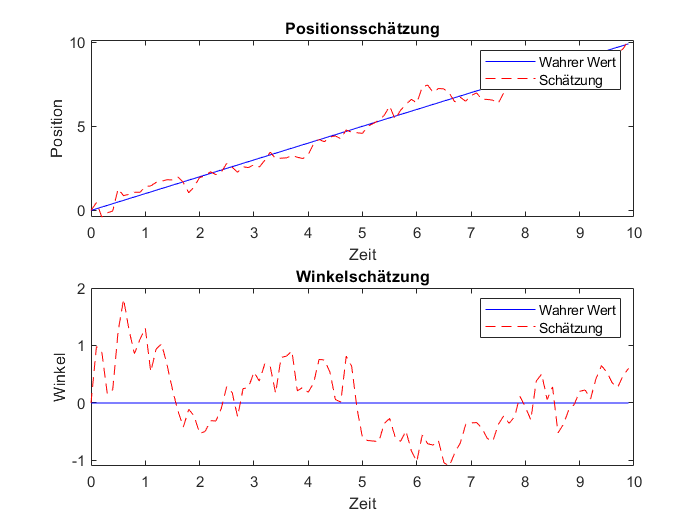

% Parameter des Modells
dt = 0.1;                   % Zeitschritt
num_steps = 100;            % Anzahl der Zeitschritte

% Wahrer Zustandsvektor
x_true = zeros(2, num_steps);

% Anfangszustand
x_true(:, 1) = [0; 0];

% Prozessrauschen (Q) und Messrauschen (R)
Q = diag([0.1, 0.1]);
R = diag([1, 1]);

% Zustandsübergangsfunktion
f = @(x, u) [x(1) + dt * cos(x(2)); x(2) + dt * sin(x(2))];

% Beobachtungsfunktion
h = @(x) x;

% Jacobimatrix der Zustandsübergangsfunktion
F = @(x, u) [1 - dt * sin(x(2)), dt * cos(x(2)); dt * cos(x(2)), 1 + dt * sin(x(2))];

% Jacobimatrix der Beobachtungsfunktion
H = @(x) eye(2);

% Anfangsschätzung
x_est = zeros(2, num_steps);

% Anfangsschätzung der Kovarianzmatrix
P_est = eye(2);

% EKF Schleife
for k = 2:num_steps
    % Wahrer Zustand durch Zustandsübergang aktualisieren
    x_true(:, k) = f(x_true(:, k-1));
    
    % Messung simulieren
    z = h(x_true(:, k)) + sqrt(R) * randn(2, 1);
    
    % Vorhersage
    x_pred = f(x_est(:, k-1));
    P_pred = F(x_est(:, k-1)) * P_est * F(x_est(:, k-1))' + Q;
    
    % Kalman-Gain berechnen
    K = P_pred * H(x_pred)' * inv(H(x_pred) * P_pred * H(x_pred)' + R);
    
    % Schätzung aktualisieren
    x_est(:, k) = x_pred + K * (z - h(x_pred));
    P_est = (eye(2) - K * H(x_pred)) * P_pred;
end

% Ergebnisse anzeigen
t = dt * (0:num_steps-1);
figure;
subplot(2,1,1);
plot(t, x_true(1,:), 'b-', t, x_est(1,:), 'r--');
xlabel('Zeit');
ylabel('Position');
legend('Wahrer Wert', 'Schätzung');
title('Positionsschätzung');
subplot(2,1,2);
plot(t, x_true(2,:), 'b-', t, x_est(2,:), 'r--');
xlabel('Zeit');
ylabel('Winkel');
legend('Wahrer Wert', 'Schätzung');
title('Winkelschätzung');

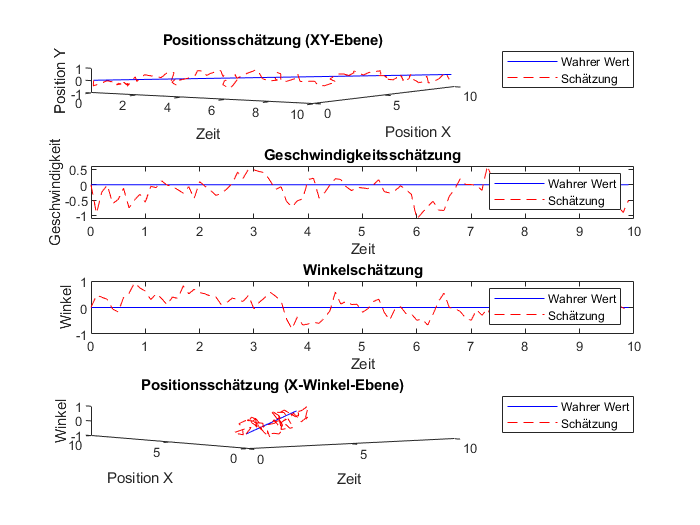

% Parameter des Modells
dt = 0.1;                   % Zeitschritt
num_steps = 100;            % Anzahl der Zeitschritte

% Wahrer Zustandsvektor
x_true = zeros(4, num_steps);

% Anfangszustand
x_true(:, 1) = [0; 0; 0; 0];

% Prozessrauschen (Q) und Messrauschen (R)
Q = diag([0.1, 0.1, 0.1, 0.1]);
R = diag([1, 1, 1, 1]);

% Zustandsübergangsfunktion
f = @(x, u) [x(1) + dt * cos(x(4)); x(2) + dt * sin(x(4)); x(3) + dt * u; x(4)];

% Beobachtungsfunktion
h = @(x) x;

% Jacobimatrix der Zustandsübergangsfunktion
F = @(x, u) [1, 0, -dt * sin(x(4)), dt * cos(x(4));
             0, 1, dt * cos(x(4)), dt * sin(x(4));
             0, 0, 1, 0;
             0, 0, 0, 1];

% Jacobimatrix der Beobachtungsfunktion
H = @(x) eye(4);

% Anfangsschätzung
x_est = zeros(4, num_steps);

% Anfangsschätzung der Kovarianzmatrix
P_est = eye(4);

% EKF Schleife
for k = 2:num_steps
    % Wahrer Zustand durch Zustandsübergang aktualisieren
    x_true(:, k) = f(x_true(:, k-1), 0);
    
    % Messung simulieren
    z = h(x_true(:, k)) + sqrt(R) * randn(4, 1);
    
    % Vorhersage
    x_pred = f(x_est(:, k-1), 0);
    P_pred = F(x_est(:, k-1), 0) * P_est * F(x_est(:, k-1), 0)' + Q;
    
    % Kalman-Gain berechnen
    K = P_pred * H(x_pred)' * inv(H(x_pred) * P_pred * H(x_pred)' + R);
    
    % Schätzung aktualisieren
    x_est(:, k) = x_pred + K * (z - h(x_pred));
    P_est = (eye(4) - K * H(x_pred)) * P_pred;
end

% Ergebnisse anzeigen
t = dt * (0:num_steps-1);
figure;
subplot(4,1,1);
plot3(t, x_true(1,:), x_true(2,:), 'b-', t, x_est(1,:), x_est(2,:), 'r--');
xlabel('Zeit');
ylabel('Position X');
zlabel('Position Y');
legend('Wahrer Wert', 'Schätzung');
title('Positionsschätzung (XY-Ebene)');
subplot(4,1,2);
plot(t, x_true(3,:), 'b-', t, x_est(3,:), 'r--');
xlabel('Zeit');
ylabel('Geschwindigkeit');
legend('Wahrer Wert', 'Schätzung');
title('Geschwindigkeitsschätzung');
subplot(4,1,3);
plot(t, x_true(4,:), 'b-', t, x_est(4,:), 'r--');
xlabel('Zeit');
ylabel('Winkel');
legend('Wahrer Wert', 'Schätzung');
title('Winkelschätzung');
subplot(4,1,4);
plot3(t, x_true(1,:), x_true(4,:), 'b-', t, x_est(1,:), x_est(4,:), 'r--');
xlabel('Zeit');
ylabel('Position X');
zlabel('Winkel');
legend('Wahrer Wert', 'Schätzung');
title('Positionsschätzung (X-Winkel-Ebene)');

% Anfangsposition und Anfangsgeschwindigkeit
R_0 = [0; 0; 0];
V_0 = [0; 0; 0];

% Zeitbereich auf eine Minute erweitert
t = linspace(0, 120, 240);

% A ist eine Matrix, die die Beschleunigung in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
A = [1 * cos(t/12); 0.5 * sin(t/12); 0.05 * ones(size(t/12))]; 

% V ist eine Matrix, die die Geschwindigkeit in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
V = cumtrapz(t/12, A, 2) + V_0;

% R ist eine Matrix, die die Position in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
Bewegungsgleichung = R_0 + cumtrapz(t/12, V, 2) + 0.5 * cumtrapz(t/12, A, 2) .* t;

% Parameter des Modells
dt = t(2) - t(1);           % Zeitschritt
num_steps = numel(t);       % Anzahl der Zeitschritte

% Wahrer Zustandsvektor
x_true = zeros(6, num_steps);

% Anfangszustand
x_true(1:3, 1) = R_0;
x_true(4:6, 1) = V_0;

% Prozessrauschen (Q) und Messrauschen (R)
Q = diag([0.1, 0.1, 0.1, 0.1, 0.1, 0.1]);
R = diag([1, 1, 1, 1, 1, 1]);

% Zustandsübergangsfunktion
f = @(x, u) [x(1:3) + dt * x(4:6);
             x(4:6) + dt * u];

% Beobachtungsfunktion
h = @(x) x;

% Jacobimatrix der Zustandsübergangsfunktion
F = @(x, u) [eye(3), dt * eye(3);
             zeros(3), eye(3)];

% Jacobimatrix der Beobachtungsfunktion
H = @(x) eye(6);

% Positionen der Radarsensoren
pos_radar1 = [10; 0; 0];
pos_radar2 = [-10; 0; 0];

% Berechnung der Winkel und Abstände für die Kalman-Schätzung
dist_matrix_radar1 = [];
dist_matrix_radar2 = [];
dist_3dmatrix_radar1 = [];
dist_3dmatrix_radar2 = [];
alpha_vertikal_radar1 = [];
alpha_vertikal_radar2 = [];
alpha_horizontal_radar1 = [];
alpha_horizontal_radar2 = [];

for i = 1:num_steps
    % Berechnung des absoluten Abstands im 3D-Raum
    dist_radar1 = vecnorm(R(:, i) - pos_radar1);
    dist_radar2 = vecnorm(R(:, i) - pos_radar2);
    dist_matrix_radar1 = [dist_matrix_radar1; dist_radar1];
    dist_matrix_radar2 = [dist_matrix_radar2; dist_radar2];
    
    % Berechnung des Abstands separat in x-, y- und z-Richtung
    dist3d_radar1 = R(:, i) - pos_radar1;
    dist3d_radar2 = R(:, i) - pos_radar2;
    dist_3dmatrix_radar1 = [dist_3dmatrix_radar1; dist3d_radar1'];
    dist_3dmatrix_radar2 = [dist_3dmatrix_radar2; dist3d_radar2'];
    
    % Berechnung der Winkel nach oben (vertikal) von Radar 1
    delta_z = R(3, i) - pos_radar1(3);
    delta_y = R(2, i) - pos_radar1(2);
    alpha_vertikal_radar1 = [alpha_vertikal_radar1; atan2(delta_z, delta_y)];
    
    % Berechnung der Winkel nach oben (vertikal) von Radar 2
    delta_z = R(3, i) - pos_radar2(3);
    delta_x = R(1, i) - pos_radar2(1);
    alpha_vertikal_radar2 = [alpha_vertikal_radar2; atan2(delta_z, delta_x)];
    
    % Berechnung der Winkel nach rechts und links (horizontal) von Radar 1
    delta_x = R(1, i) - pos_radar1(1);
    delta_y = R(2, i) - pos_radar1(2);
    alpha_horizontal_radar1 = [alpha_horizontal_radar1; atan2(delta_x, delta_y)];
    
    % Berechnung der Winkel nach rechts und links (horizontal) von Radar 2
    delta_y = R(2, i) - pos_radar2(2);
    delta_x = R(1, i) - pos_radar2(1);
    alpha_horizontal_radar2 = [alpha_horizontal_radar2; atan2(delta_y, delta_x)];
end

Matrix dimensions must agree.


% Anfangsschätzung
x_est = zeros(6, num_steps);

% Anfangsschätzung der Kovarianzmatrix
P_est = eye(6);

% EKF Schleife
for k = 2:num_steps
    % Wahrer Zustand durch Zustandsübergang aktualisieren
    x_true(:, k) = f(x_true(:, k-1), 0);
    
    % Messung simulieren
    z = [R(:, k); alpha_horizontal_radar1(k); alpha_horizontal_radar2(k); alpha_vertikal_radar1(k); alpha_vertikal_radar2(k)] + sqrt(R) * randn(6, 1);
    
    % Vorhersage
    x_pred = f(x_est(:, k-1), 0);
    P_pred = F(x_est(:, k-1), 0) * P_est * F(x_est(:, k-1), 0)' + Q;
    
    % Kalman-Gain berechnen
    K = P_pred * H(x_pred)' * inv(H(x_pred) * P_pred * H(x_pred)' + R);
    
    % Schätzung aktualisieren
    x_est(:, k) = x_pred + K * (z - h(x_pred));
    P_est = (eye(6) - K * H(x_pred)) * P_pred;
end

% Ergebnisse anzeigen
figure;
subplot(3,2,1);
plot3(R(1,:), R(2,:), R(3,:), 'b-', x_est(1,:), x_est(2,:), x_est(3,:), 'r--');
xlabel('X');
ylabel('Y');
zlabel('Z');
legend('Wahrer Wert', 'Schätzung');
title('Positionsschätzung');
subplot(3,2,2);
plot(t, V(1,:), 'b-', t, x_est(4,:), 'r--');
xlabel('Zeit');
ylabel('Geschwindigkeit X');
legend('Wahrer Wert', 'Schätzung');
title('Geschwindigkeitsschätzung (X)');
subplot(3,2,3);
plot(t, V(2,:), 'b-', t, x_est(5,:), 'r--');
xlabel('Zeit');
ylabel('Geschwindigkeit Y');
legend('Wahrer Wert', 'Schätzung');
title('Geschwindigkeitsschätzung (Y)');
subplot(3,2,4);
plot(t, V(3,:), 'b-', t, x_est(6,:), 'r--');
xlabel('Zeit');
ylabel('Geschwindigkeit Z');
legend('Wahrer Wert', 'Schätzung');
title('Geschwindigkeitsschätzung (Z)');
subplot(3,2,5);
plot(t, R(4,:), 'b-', t, x_est(1,:), 'r--');
xlabel('Zeit');
ylabel('Winkel X');
legend('Wahrer Wert', 'Schätzung');
title('Winkelschätzung (X)');
subplot(3,2,6);
plot(t, R(5,:), 'b-', t, x_est(2,:), 'r--');
xlabel('Zeit');
ylabel('Winkel Y');
legend('Wahrer Wert', 'Schätzung');
title('Winkelschätzung (Y)');



R_0 = [0; 0; 0];  % Anfangsposition (Nullvektor)
V_0 = [0; 0; 0];  % Anfangsgeschwindigkeit (Nullvektor)
t = linspace(0, 120, 240); % Zeitbereich auf eine Minute erweitert

% A ist eine Matrix, die die Beschleunigung in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
% Die Beschleunigung wird durch trigonometrische Funktionen erzeugt.
A = [1 * cos(t/12); 0.5 * sin(t/12); 0.05 * ones(size(t/12))]; 

% V ist eine Matrix, die die Geschwindigkeit in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
% Die Geschwindigkeit wird durch numerische Integration der Beschleunigung berechnet.
% Die Anfangsgeschwindigkeit V_0 wird hinzugefügt.
V = cumtrapz(t/12, A, 2) + V_0;


% R ist eine Matrix, die die Position in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
% Die Position wird durch numerische Integration der Geschwindigkeit und Beschleunigung berechnet.
% Der Anfangsposition R_0 und zusätzlichen Ausdrücken für die Berücksichtigung der Beschleunigung während der Bewegung wird hinzugefügt.
R = R_0 + cumtrapz(t/12, V, 2) + 0.5 * cumtrapz(t/12, A, 2) .* t;

pos_radar1 = [0, -10, 0];  % Position des Radar 1: x=0, y=-10, z=0
pos_radar2 = [-50, 30, 0];  % Position des Radar 2: x=-50, y=30, z=0

R_transposed = transpose(R);  % Transponiert die Matrix R

dist_matrix_radar1 = [];
dist_matrix_radar2 = [];

dist_3dmatrix_radar1 = [];
dist_3dmatrix_radar2 = [];

for i = 1:length(R_transposed)
    
    %Berechnung des Absoluten Abstand im 3D-Raum
    dist_radar1 = norm(R_transposed(i, :) - pos_radar1);  % Berechnet den Abstand zwischen der i-ten Zeile von R_transposed und pos_radar1
    dist_radar2 = norm(R_transposed(i, :) - pos_radar2);  % Berechnet den Abstand zwischen der i-ten Zeile von R_transposed und pos_radar2
    
    dist_matrix_radar1 = [dist_matrix_radar1; dist_radar1];  % Fügt den Abstand dist_radar1 der dist_matrix_radar1 hinzu
    dist_matrix_radar2 = [dist_matrix_radar2; dist_radar2];  % Fügt den Abstand dist_radar2 der dist_matrix_radar2 hinzu
    
    %Berechnung des Abstands seperat in x,y,z Richtung
    dist3d_radar1 = [R(1,i)-pos_radar1(1), R(2,i)-pos_radar1(2), R(3,i)-pos_radar1(3)];  % Berechnet den 3D-Abstand zwischen R(:,i) und pos_radar1
    dist3d_radar2 = [R(1,i)-pos_radar2(1), R(2,i)-pos_radar2(2), R(3,i)-pos_radar2(3)];  % Berechnet den 3D-Abstand zwischen R(:,i) und pos_radar2
    
    dist_3dmatrix_radar1 = [dist_3dmatrix_radar1; dist3d_radar1];  % Fügt den 3D-Abstand dist3d_radar1 der dist_3dmatrix_radar1 hinzu
    dist_3dmatrix_radar2 = [dist_3dmatrix_radar2; dist3d_radar2];  % Fügt den 3D-Abstand dist3d_radar2 der dist_3dmatrix_radar2 hinzu

end

dist_matrix_radar1  % Gibt die dist_matrix_radar1 aus
dist_matrix_radar2  % Gibt die dist_matrix_radar2 aus

dist_3dmatrix_radar1  % Gibt die dist_3dmatrix_radar1 aus
dist_3dmatrix_radar2  % Gibt die dist_3dmatrix_radar2 aus

theta_radar1 = [];  % Leerer Vektor für die Azimutwinkel von Radar 1
theta_radar2 = [];  % Leerer Vektor für die Azimutwinkel von Radar 2

phi_radar1 = [];  % Leerer Vektor für die Elevationswinkel von Radar 1
phi_radar2 = [];  % Leerer Vektor für die Elevationswinkel von Radar 2

for i = 1:length(R_transposed)
    
    % Berechnung des Elevationswinkels (phi) für Radar 1
    delta_z = R_transposed(i,3) - pos_radar1(3);
    rho = sqrt((R_transposed(i,1) - pos_radar1(1))^2 + (R_transposed(i,2) - pos_radar1(2))^2 + delta_z^2);
    phi_radar1 = [phi_radar1; rad2deg(acos(delta_z/rho))];  % Fügt den Winkel zu phi_radar1 hinzu
    
    % Berechnung des Elevationswinkels (phi) für Radar 2
    delta_z = R_transposed(i,3) - pos_radar2(3);
    rho = sqrt((R_transposed(i,2) - pos_radar2(2))^2 + (R_transposed(i,1) - pos_radar2(1))^2 + delta_z^2);
    phi_radar2 = [phi_radar2; rad2deg(acos(delta_z/rho))];  % Fügt den Winkel zu phi_radar2 hinzu
    
    
    % Berechnung des Azimutwinkels (theta) für Radar 1
    delta_x = R_transposed(i,1) - pos_radar1(1);
    delta_y = R_transposed(i,2) - pos_radar1(2);
    theta_radar1 = [theta_radar1; rad2deg(atan2(delta_y, delta_x))];  % Fügt den Winkel zu theta_radar1 hinzu
    
    % Berechnung des Azimutwinkels (theta) für Radar 2
    delta_x = R_transposed(i,2) - pos_radar2(2);
    delta_y = R_transposed(i,1) - pos_radar2(1);
    theta_radar2 = [theta_radar2; rad2deg(atan2(delta_y, delta_x))];  % Fügt den Winkel zu theta_radar2 hinzu   
end

phi_radar1  % Gibt die Elevationswinkel von Radar 1 aus
phi_radar2  % Gibt die Elevationswinkel von Radar 2 aus

theta_radar1  % Gibt die Azimutwinkel von Radar 1 aus
theta_radar2  % Gibt die Azimutwinkel von Radar 2 aus

polar_koordinaten_radar1 = [dist_matrix_radar1, theta_radar1, phi_radar1]
polar_koordinaten_radar2 = [dist_matrix_radar2, theta_radar2, phi_radar2]